# Tikhonov regularization implementation

load ifk.mat

[m,n] = size(d);
a = 0; b = 1;

n = m;

sig  = 1e-4;

dx = (b-a)/m;
g = @(x,y) x*exp(-x*y);

x = [];
for j = 1:n
    x = [x  a + (dx/2) + (j-1)*dx]; %form x
end
y = x;

G = zeros(m,n);

for i = 1:m
    for j = 1:n
        G(i,j) = g(x(j),y(i)).*dx; %form G
    end
end

% Get the singular values for the system matrix
%[U,S,V] = svd(G);

### No.1 Use the L-curve to find a value for $\alpha$.

[U,sm,X,V,W] = cgsvd(G,eye(n));

%regtools
[reg_corner,rho,eta,reg_param] = l_curve(U,sm,d,'Tikh');
alpha = reg_corner

alpha = 2.5058e-05

### No.2 (a) Identify a value for δ and justify your choice.

Using the heuristic approach, andd its the value of the residual norm at which we selected the value of alpha.

delta = sig*sqrt(m)

delta = 4.4721e-04

### b) Use your value for α from 1. to calculate $$‖Gm_{\alpha}-d‖_{2}^{2}$$.

malpha = @(alpha) inv(G'*G + (alpha^2)*eye(n))*G'*d;

discrepancy = norm(G*malpha(alpha) - d,2)^2

discrepancy = 9.4367e-09

The value of $\alpha$ satisfies the discrepancy i choose in 2(a).

### c) Implement a nonlinear solver such as fsolve in MATLAB to find a regularization parameter using the discrepancy principle.

f = @(alpha) norm(G*malpha(alpha) - d,2)^2 - delta; %non linear function
alph = fsolve(f,alpha)


Equation solved at initial point.

fsolve completed because the vector of function values at the initial point
is near zero as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


alph = 2.5058e-05

### No.3 (a) Identify a value for δreg and justify your choice.

deltareg = 20

deltareg = 20

### (b) Use your values for α from 1 and 2c to calculate$$‖Gm_{\alpha}-d‖_{2}^{2}$$$/ \sigma^{2}$$+ \alpha^{2}||m_{\alpha}||_{2}^{2}$. Discuss if these choices of α satisfy the regularized discrepancy you chose in 3a.

reg_d = @(alpha) (norm(G*malpha(alpha) - d)^2)/(sig^2) + (alpha^2)*norm(malpha(alpha))^2;

regd_1 = reg_d(alpha)

regd_1 = 0.9437


regd_2c = reg_d(alph)

regd_2c = 0.9437

The choices of the values of alpha give as $\delta_{reg}$ values less than $\delta_{reg}$$$ = 20$$, which we chose in 3a, hence satisfying the regularized discrepancy.

### (c) Implement a nonlinear solver such as fsolve in MATLAB to find a regularization parameter using the regularized discrepancy principle.

freg = @(alpha) (norm(G*malpha(alpha) - d)^2)/(sig^2) + (alpha^2)*norm(malpha(alpha))^2 - deltareg;

al = fsolve(freg,alph)


Equation solved, inaccuracy possible.

The vector of function values is near zero, as measured by the value
of the function tolerance. However, the last step was ineffective.

<stopping criteria details>


al = 6.7486e-04

### No.4 Plot model parameter estimates using Tikhonov regularization with all three values of α on the same graph. Relate the shape of the different graphs to the corresponding values for α.

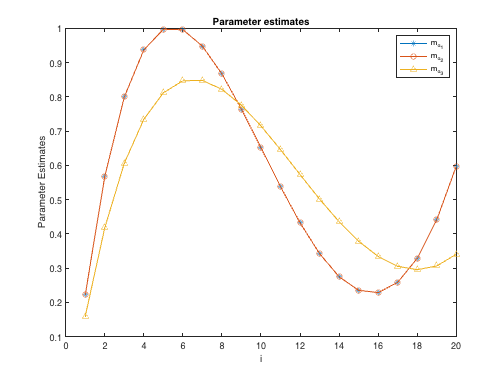

alpha = [alpha alph al];

m1 = malpha(alpha(1));
m2 = malpha(alpha(2));
m3 = malpha(alpha(3));

figure(2)
plot(m1,'-*'); hold on
plot(m2,'-o'); hold on
plot(m3,'-^')
legend('m_{\alpha_{1}}','m_{\alpha_{2}}','m_{\alpha_{3}}')
xlabel('i'); ylabel('Parameter Estimates')
title('Parameter estimates')

The smaller  the value of alpha, the better the shape of the curve. As the graph for alpha = 2.5058e-5, gives as better estimates than that of  alpha = 6.7486e-4  

### No.5 (i) Plot the resolution matrices from each value of α

Gp = @(alpha) inv(G'*G + (alpha^2)*eye(n))*G';

figure(2)
clf
colormap('gray')
subplot(2,2,1)
imagesc((Gp(alpha(1)))*G)
set(colorbar,'Fontsize',18);

xlabel('j')
ylabel('i')
title('Model resolution matrix \alpha_{1}')

subplot(2,2,2)
imagesc((Gp(alpha(2)))*G)
set(colorbar,'Fontsize',18);

xlabel('j')
ylabel('i')
title('Model resolution matrix \alpha_{2}')
subplot(2,2,3)
imagesc((Gp(alpha(3)))*G)
set(colorbar,'Fontsize',18);

xlabel('j')
ylabel('i')
title('Model resolution matrix \alpha_{3}')

According to the graphs, for all the values of alpha, the diagonal elements are somehow smeared compared to others, however m20 is well resolved compared to all other estimates. 

### (ii) Plot the diagonal elements of the resolution matrices on the same graph.

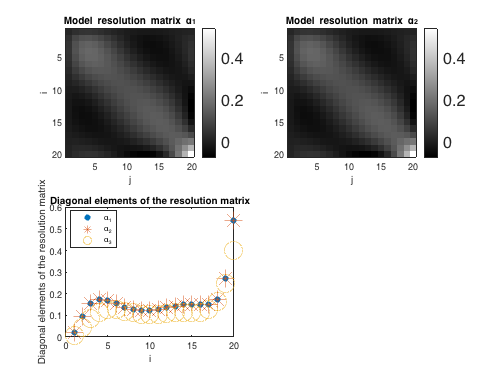

figure(3)
plot(diag(Gp(alpha(1))*G),'.','MarkerSize',20); hold on
plot(diag(Gp(alpha(2))*G),'*','MarkerSize',20); hold on
plot(diag(Gp(alpha(3))*G),'o','MarkerSize',20); 
legend('\alpha_{1}','\alpha_{2}','\alpha_{3}',Location='best')
xlabel('i'); ylabel('Diagonal elements of the resolution matrix')
title('Diagonal elements of the resolution matrix')

### Identify where the resolution is best and worst in each case. Give an overall assessment of how well we are able to resolve the model parameters.

The resolution is best at m20 parameter estimates, and worst at off diagonal elements e.g. m1,m2,..,m18. Based on the tests about, the different values of alpha, i believe a best approach to resolve the model parameters, is to use a better method of finding good alpha values which will give as better estimates, hence giving as better resolution matrix.